%load in data
load 'HadISST.mat'
load  'SeaWIFS.mat'

**Manipulating Datasets to have the same time overlap **

%create array time_common that has the common time found with the intersect function 
[time_common,ind,ind_sw]=intersect(time,time_sw);

%indexing so time SST and NPP have the same common time period
time = time(ind);
sst=sst(ind,:,:);

time_sw = time(ind_sw);
NPP_sw=NPP_sw(ind_sw,:,:);

**Calculating Anomalies from Climatologies **

%calculate climatology datasets for SST and NPP 
for m=1:12
    climSST(m,:,:)=mean(sst(m:12:end,:,:)); %every 12th sst in the firest dimension. keep 2nd and 3rd dimensions
    climNPP(m,:,:)=mean(NPP_sw(m:12:end,:,:));
end

%Calculate anomalies of SST and NPP from the climatologies
for t=1:length(time)
    month=mod(t,12);
    if month==0
        month=12;
    end
    anomSST(t,:,:)=sst(t,:,:)-climSST(month,:,:);
    anomNPP(t,:,:)=NPP_sw(t,:,:)-climNPP(month,:,:);
end

**Figure 1. Animation of SST and NPP Anomalies over time **

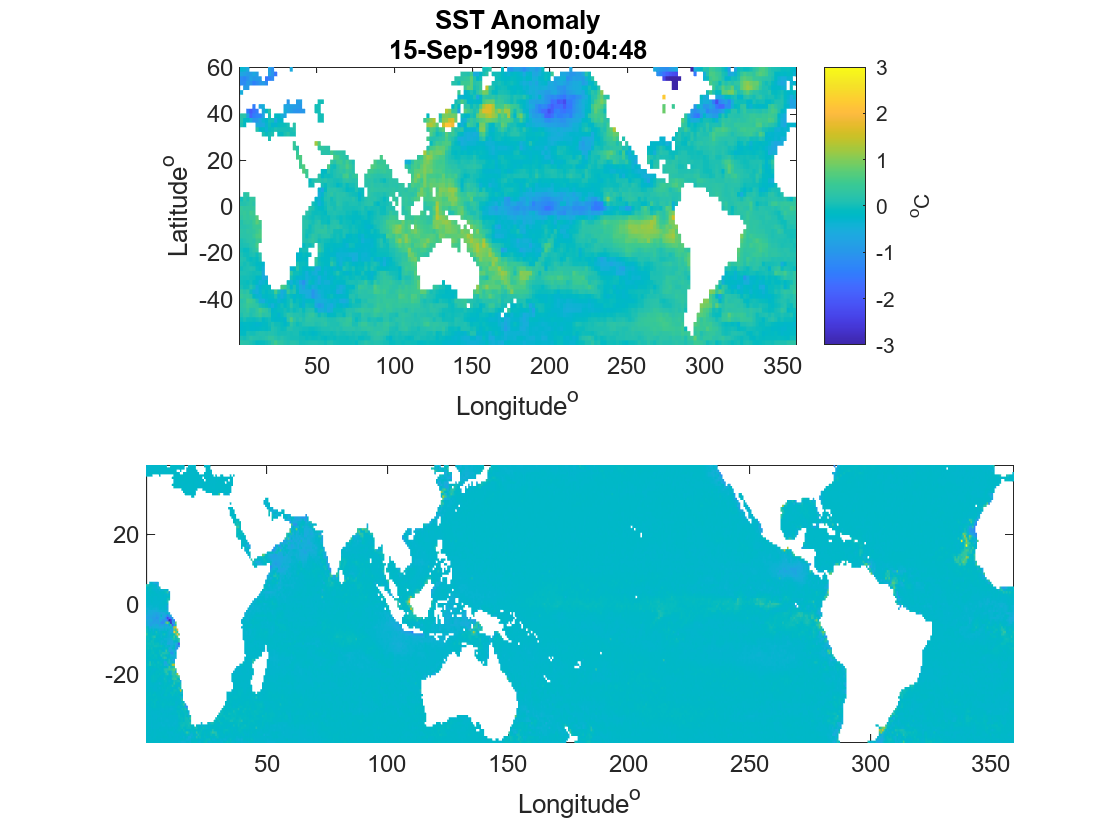

for t=1:length(time)
    daydec=time(t)-floor(time(t));
    day=daydec*365;
    date=datestr(datenum(floor(time(t)),0,day));

    clf
    subplot(2,1,1)
    pcolor(lon, lat, squeeze(anomSST(t,:,:)))
    shading flat
    clim([-3 3])
    xlabel('Longitude^o'), ylabel('Latitude^o'), title(["SST Anomaly", datestr(date)])
    pbaspect([2 1 1])
    c1=colorbar();
    c1.Label.String='^oC';

    subplot(2,1,2)
    pcolor(lon_sw, lat_sw, squeeze(anomNPP(t,:,:)))
    shading flat
    xlabel('Longitude^o'), ylabel('Latitude^o'), title(["NPP Anomaly", datestr(date)])
    axis equal tight
    clim([-100 100])
    pbaspect([2 1 1])
    c2=colorbar();
    c2.Label.String='mgC/m2/day';
    pause(0.1)
    
end 

**Is there a correlation between SST and NPP in the Eastern Equatorial Pacific?**

%finding the SST anomalies in the Equatorial Pacific Nino Region creating
%the Nino34
mylats=find(lat>=-5 & lat<=5);
mylons=find(lon>=190 & lon<=240);
nino34=squeeze(mean(mean(anomSST(:,mylats,mylons),2),3));

%finding the NPP anomalies in the Equatorial Pacific Nino Region creating
%the Nino34 for NPP
mylats_sw=find(lat_sw>=-5 & lat_sw<=5);
mylons_sw=find(lon_sw>=190 & lon_sw<=240);
NPPnino34=squeeze(nanmean(nanmean(anomNPP(:,mylats_sw,mylons_sw),2),3));


[r,p]=corrcoef(nino34,NPPnino34)


** Could this have been a La Nina event?**

** Figure 2. Regression Map of NPP onto a negative NINO34**

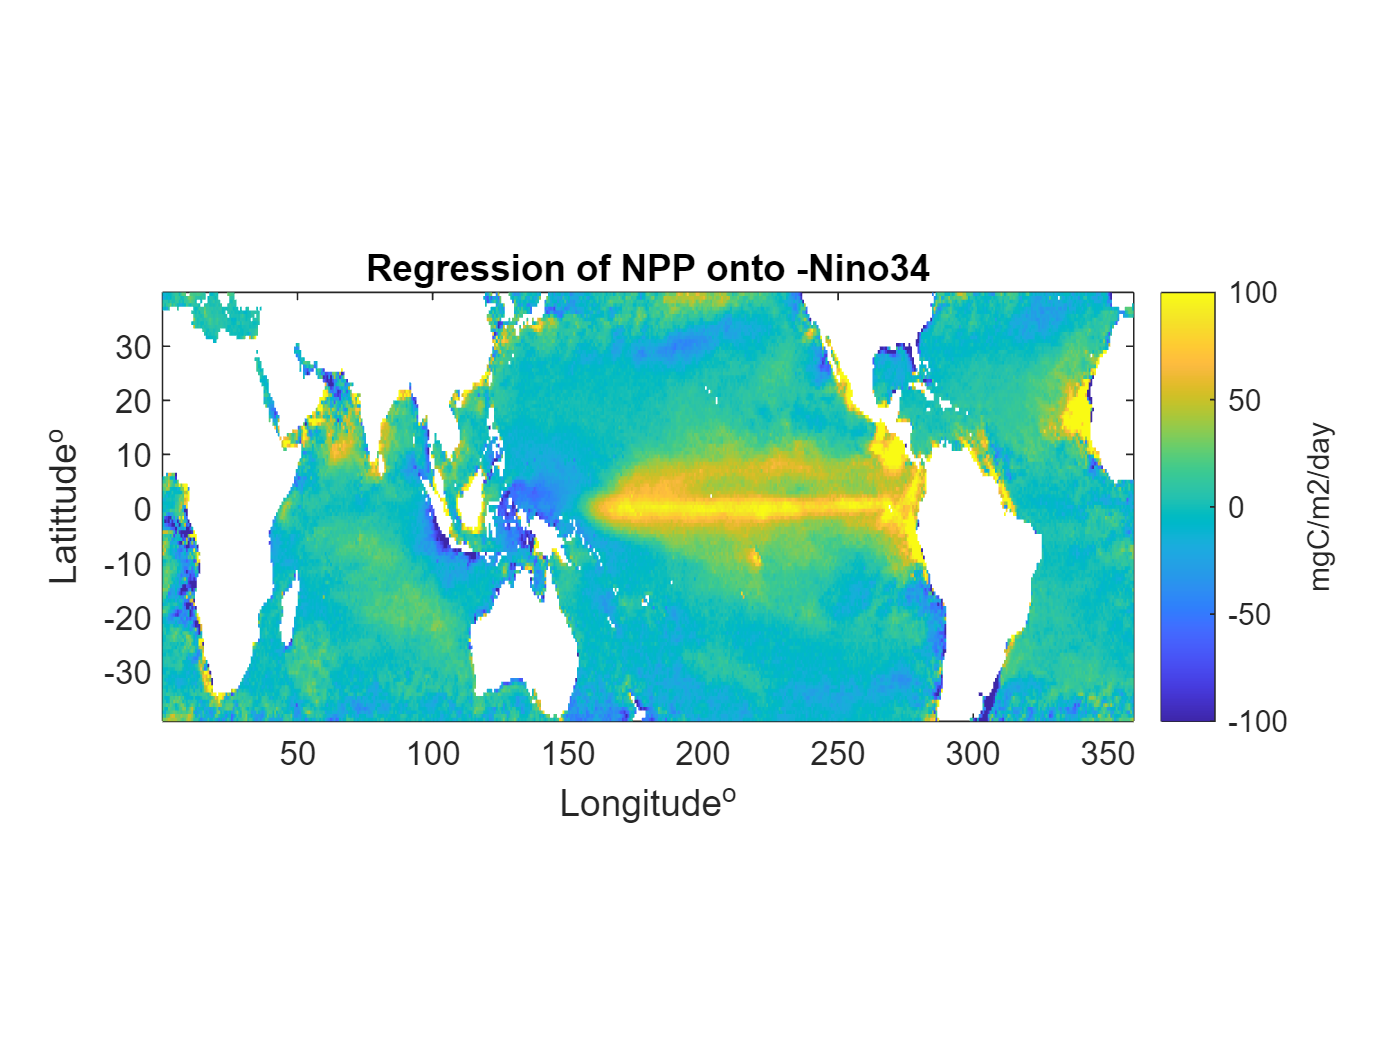

regNPP = NaN(length(lat_sw), length(lon_sw)); % Initialize the regression map
clf
for i = 1:length(lon_sw)
    for j = 1:length(lat_sw)
        if isfinite(squeeze(anomNPP(:, j, i)))
            % Code for ocean points
            reg = regress(squeeze(anomNPP(:, j, i)), -nino34);
            regNPP(j, i) = reg; % Store the regression value in the map
        else
            regNPP(j, i) = NaN; % Set the regression map at land point to NaN
        end
    end
end
pcolor(lon_sw, lat_sw, regNPP)
shading flat
xlabel('Longitude^o')
ylabel('Latittude^o')
title('Regression of NPP onto -Nino34') %tells us typical spatial distribution of NPP of el Nino
c3=colorbar();c3.Label.String=('mgC/m2/day');clim([-100 100])
daspect([2 1 1])

**Response**

Going through the animation in Figure 1, a positive anomaly of net primary productivity (NPP) in the Equatorial Eastern Pacific grows from Nov 1999 into 2000 (Fig 1). This looks to correspond to a negative anomaly of sea surface temperature (SST) in that region (Fig. 1) . This could indicate an inverse relationship between NPP and SST in the region. When investingating the SST and NPP anomalies, there is a significant negative correlation between SST and NPP (*r*=-0.8616 *p*=0.0000) in the equatorial pacific (-5S to 5N and 190 to 240W). To see if this time could have been a La Nina event, a regression map of NPP was created onto the negative NINO34. The map can indicate a typical spatial distribution of NPP during a La Nina. Since there is higher than average NPP levels in the eastern pacific corresponding with higher SST(Fig 2), the positive anomalies seen in 1999-2000 (Fig.1) could have been in response to a La Nina. Stronger trade winds would create more divergence away from the equator moving the pacific warm pool westwards. This leads to increased upwelling of cold, nutrient-rich deep waters that contribute these high levels of primary productivy and cold SST anomalies in the Eastern Equatorial Pacific that are associated with La Nina events. 